param = struct with fields:
           fc: 2000000
         kerf: 5.0000e-05
        width: 2.5000e-04
        pitch: 3.0000e-04
    Nelements: 64
    bandwidth: 74
       radius: Inf
       height: 0.0140
        focus: 0.0600


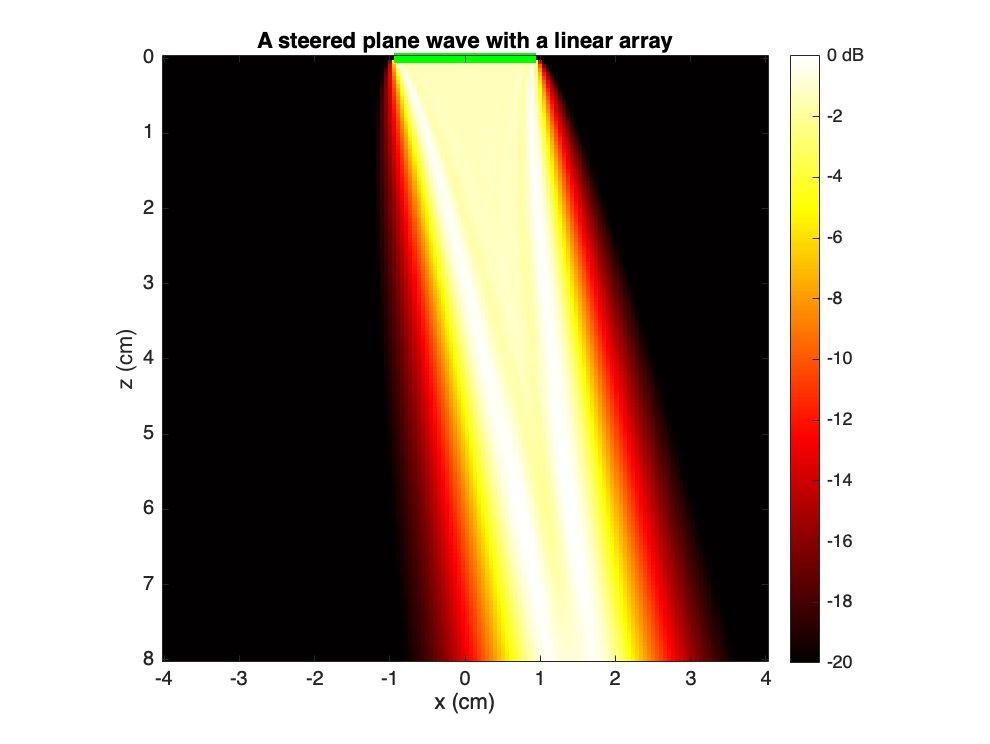

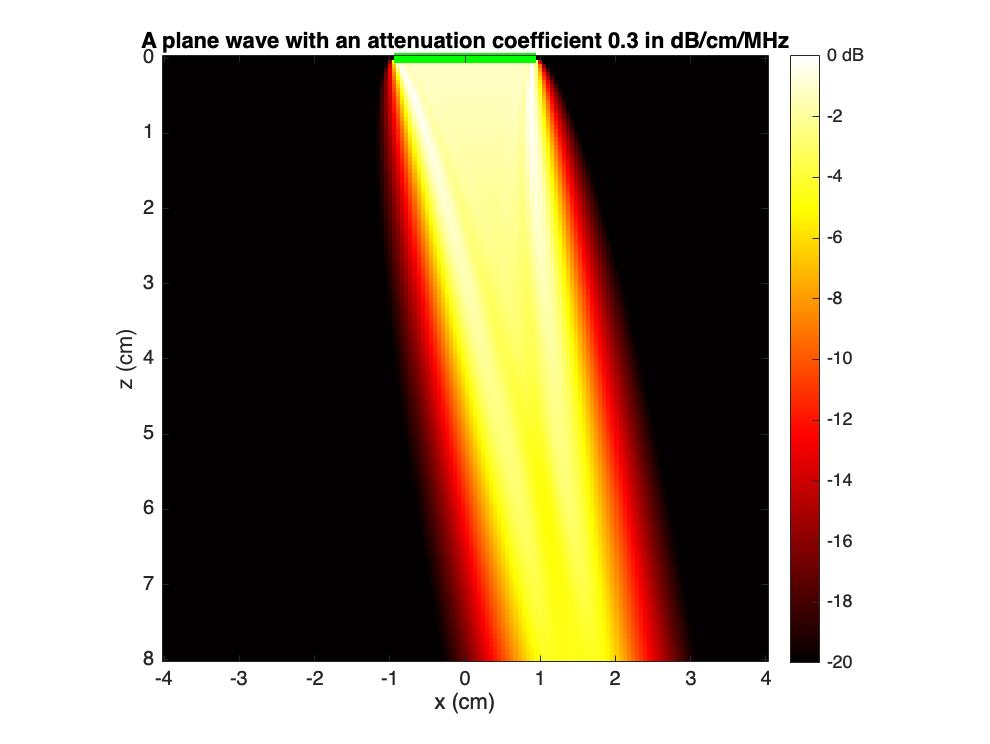

param = struct with fields:
             fc: 2700000
           kerf: 5.0000e-05
          width: 2.5000e-04
          pitch: 3.0000e-04
      Nelements: 64
      bandwidth: 74
         radius: Inf
         height: 0.0140
          focus: 0.0600
    attenuation: 0.3000


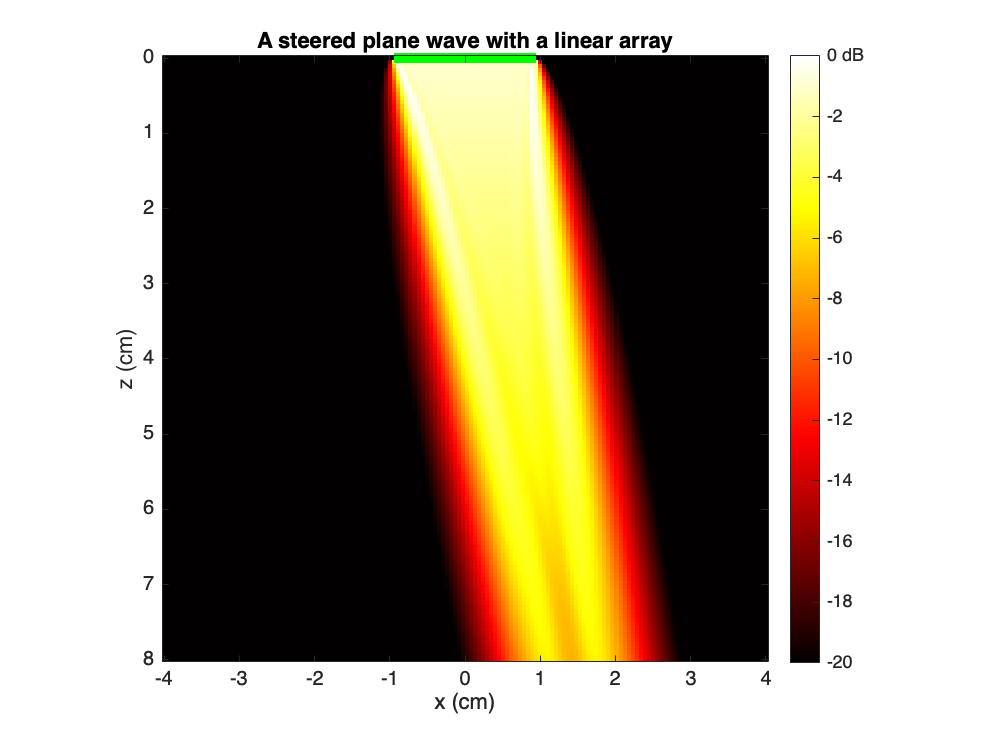

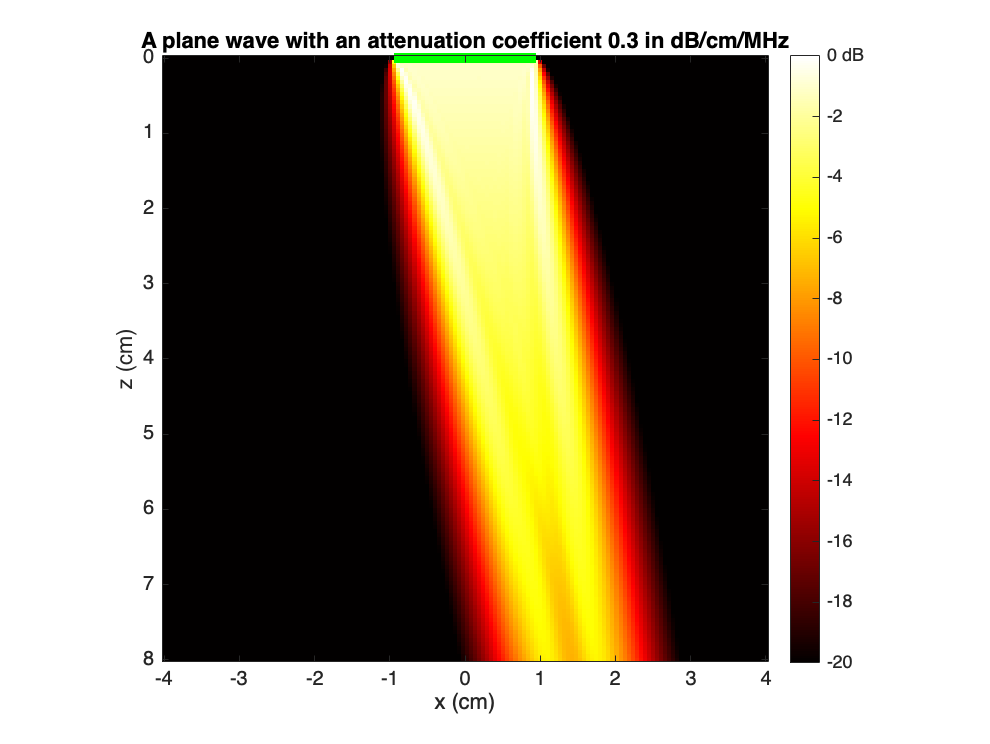

param = struct with fields:
             fc: 7000000
           kerf: 5.0000e-05
          width: 2.5000e-04
          pitch: 3.0000e-04
      Nelements: 64
      bandwidth: 74
         radius: Inf
         height: 0.0140
          focus: 0.0600
    attenuation: 0.3000


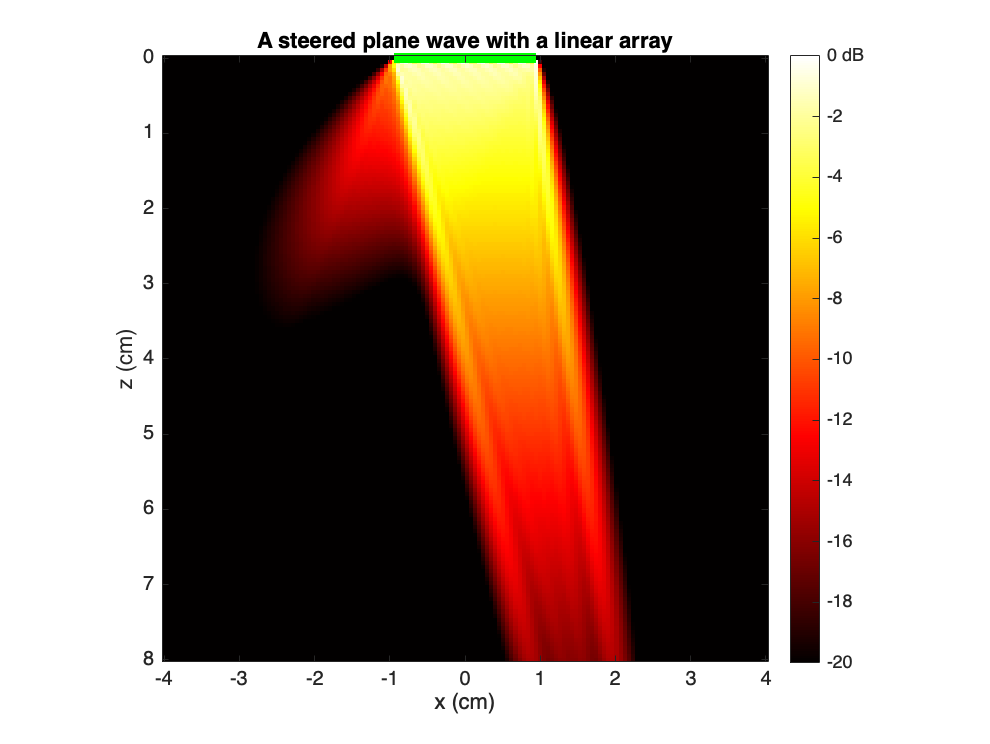

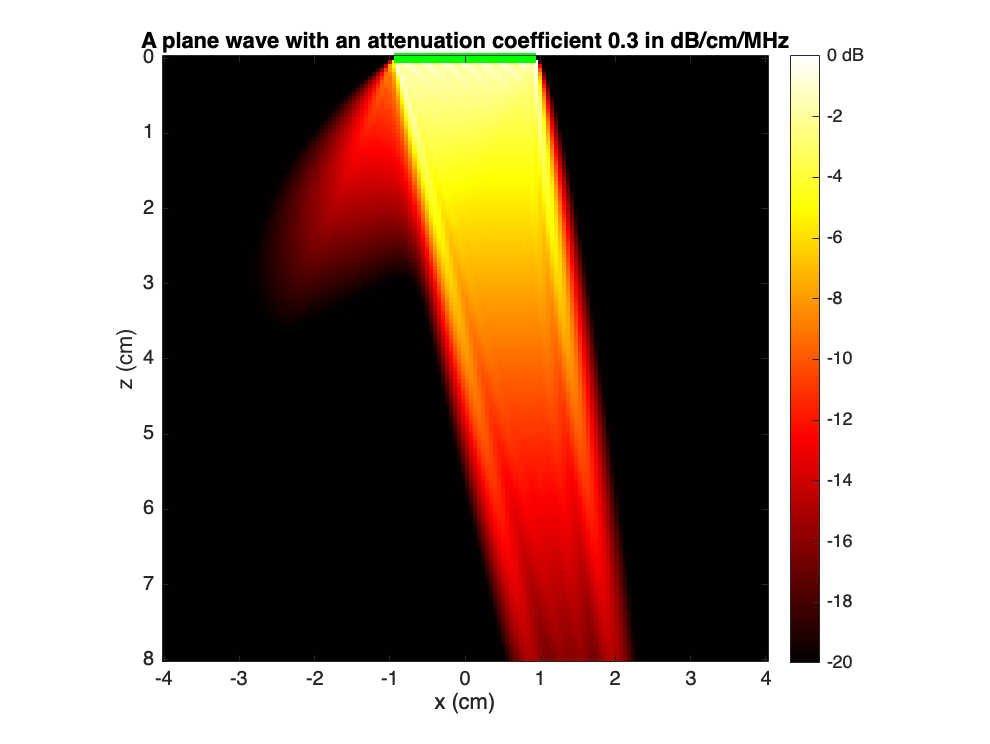

param = getparam('P4-2v');

freq_linear = [2e6, 2.7e6, 7e6]; %frequency in MhZ 

for i = 1:length(freq_linear )

    param = setfield(param,'fc',freq_linear (i))


    tilt = 10/180*pi; % tilt angle in rad
    txdel = txdelay(param,tilt); % in s
    
    
    x = linspace(-4e-2,4e-2,150); % in m
    z = linspace(0,8e-2,150); % in m
    [x,z] = meshgrid(x,z);
    
    
    P = pfield(x,z,txdel,param);
    
    
    figure
    imagesc(x(1,:)*1e2,z(:,1)*1e2,20*log10(P/max(P,[],'all')))
    caxis([-20 0]) % dynamic range = [-20,0] dB
    c = colorbar;
    c.YTickLabel{end} = '0 dB';
    colormap hot
    axis equal ij tight
    xlabel('x (cm)'), ylabel('z (cm)')
    title('A steered plane wave with a linear array')
    
    % Calculate the positions of the element centers.
    L = param.pitch*(param.Nelements-1); % array aperture (in m)
    xe = linspace(-0.5,0.5,param.Nelements)*L;
    ze = zeros(1,param.Nelements);
    hold on
    plot(xe*1e2,ze*1e2,'g','Linewidth',5)
    hold off
    %
%     arr = [0.1, 0.3, 0.5, 1.5, 2.5, 3];  % attenuation coefficient (in dB/cm/MHz)
%     for j = 1:length(arr)


%     param.attenuation = arr(j);  
    param.attenuation = 0.3;  
    P = pfield(x,z,txdel,param);
    
    figure
    imagesc(x(1,:)*1e2,z(:,1)*1e2,20*log10(P/max(P,[],'all')))
    caxis([-20 0]) % dynamic range = [-20,0] dB
    c = colorbar;
    c.YTickLabel{end} = '0 dB';
    colormap hot
    axis equal ij tight
    xlabel('x (cm)'), ylabel('z (cm)')
    title('A plane wave with an attenuation coefficient 0.3 in dB/cm/MHz')
    
    hold on
    plot(xe*1e2,ze*1e2,'g','Linewidth',5)
    hold off
%     end
end

param = struct with fields:
           fc: 2000000
         kerf: 5.0000e-05
        width: 2.5000e-04
        pitch: 3.0000e-04
    Nelements: 64
    bandwidth: 74
       radius: Inf
       height: 0.0140
        focus: 0.0600


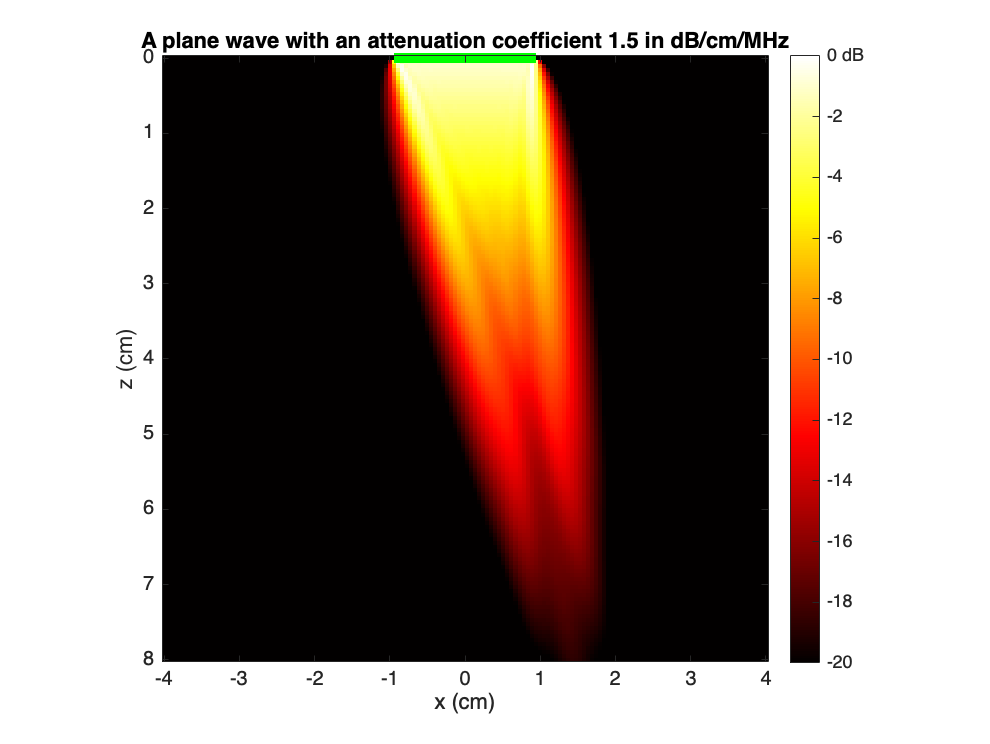

param = struct with fields:
             fc: 2700000
           kerf: 5.0000e-05
          width: 2.5000e-04
          pitch: 3.0000e-04
      Nelements: 64
      bandwidth: 74
         radius: Inf
         height: 0.0140
          focus: 0.0600
    attenuation: 1.5000


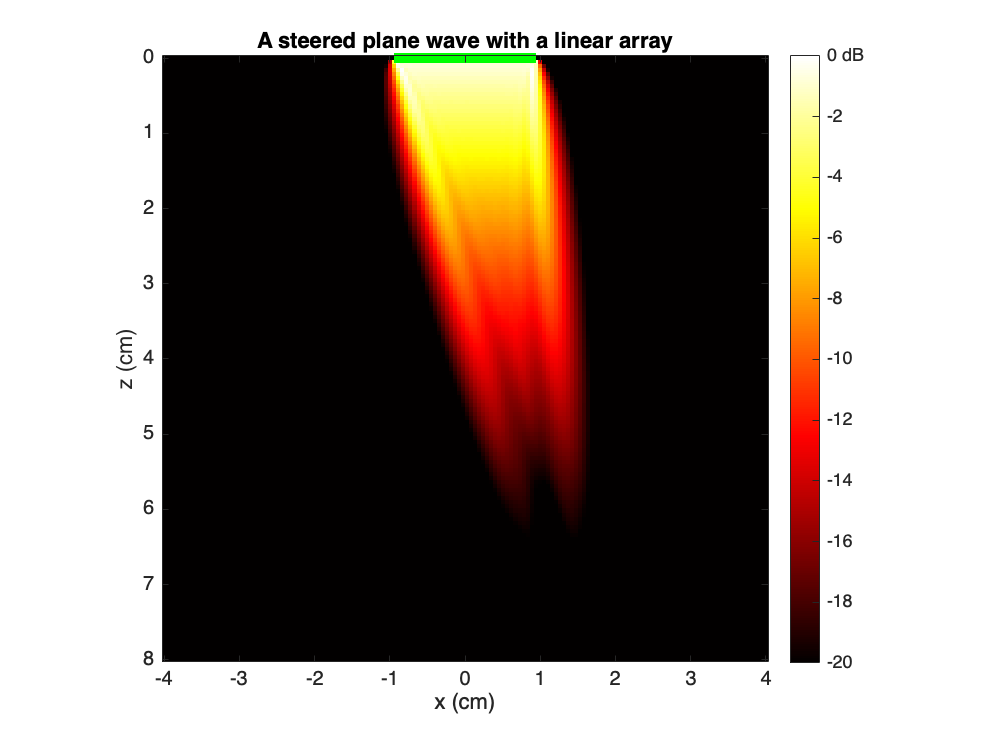

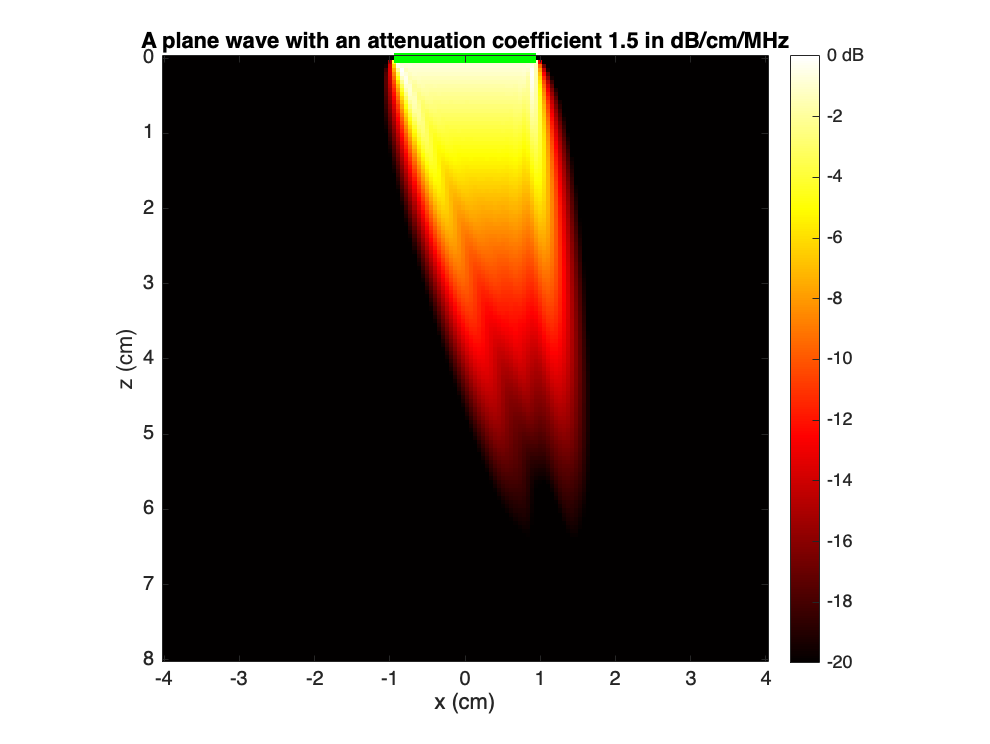

param = struct with fields:
             fc: 7000000
           kerf: 5.0000e-05
          width: 2.5000e-04
          pitch: 3.0000e-04
      Nelements: 64
      bandwidth: 74
         radius: Inf
         height: 0.0140
          focus: 0.0600
    attenuation: 1.5000


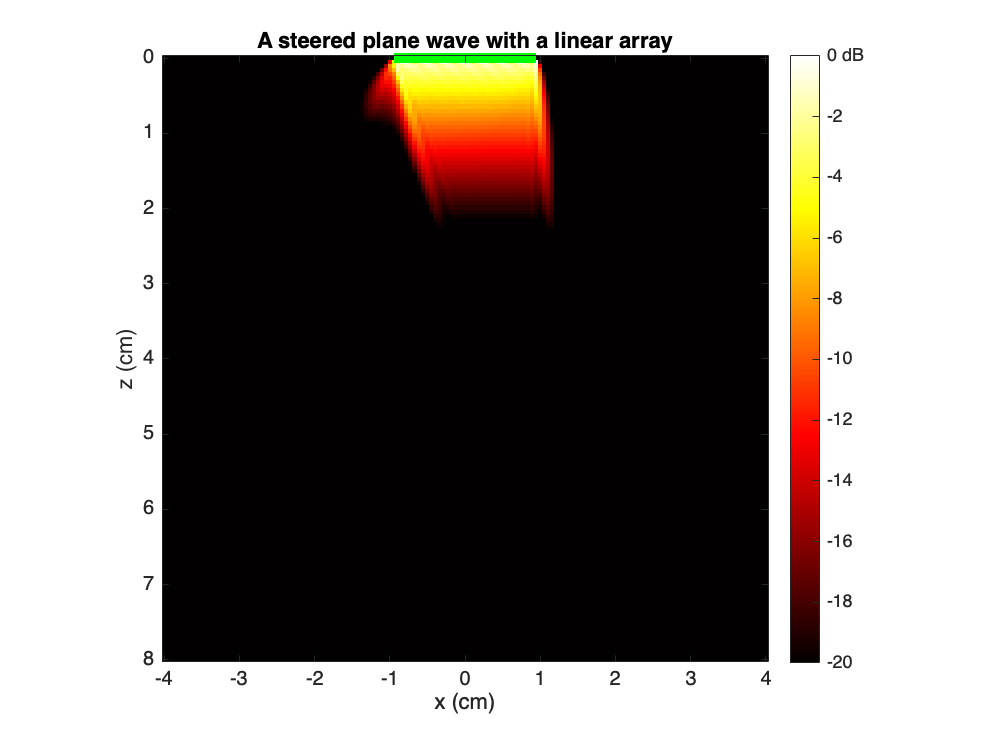

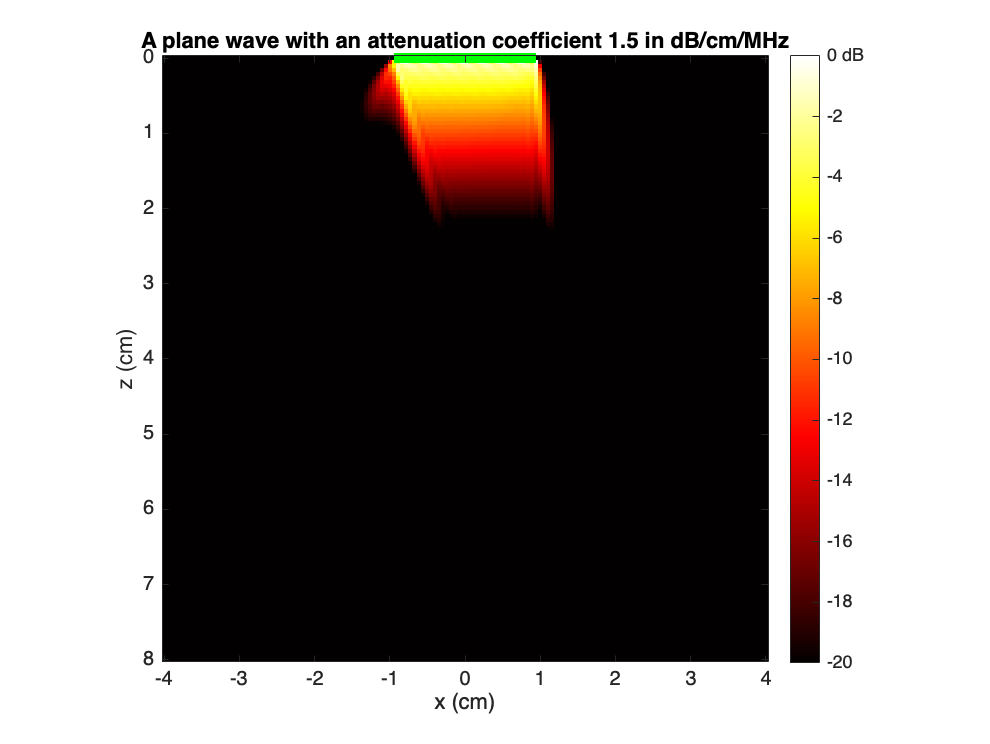

   
param = getparam('P4-2v');

freq_linear = [2e6, 2.7e6, 7e6]; %frequency in MhZ 

for i = 1:length(freq_linear )

    param = setfield(param,'fc',freq_linear (i))


    tilt = 10/180*pi; % tilt angle in rad
    txdel = txdelay(param,tilt); % in s
    
    
    x = linspace(-4e-2,4e-2,150); % in m
    z = linspace(0,8e-2,150); % in m
    [x,z] = meshgrid(x,z);
    
    
    P = pfield(x,z,txdel,param);
    
    
    figure
    imagesc(x(1,:)*1e2,z(:,1)*1e2,20*log10(P/max(P,[],'all')))
    caxis([-20 0]) % dynamic range = [-20,0] dB
    c = colorbar;
    c.YTickLabel{end} = '0 dB';
    colormap hot
    axis equal ij tight
    xlabel('x (cm)'), ylabel('z (cm)')
    title('A steered plane wave with a linear array')
    
    % Calculate the positions of the element centers.
    L = param.pitch*(param.Nelements-1); % array aperture (in m)
    xe = linspace(-0.5,0.5,param.Nelements)*L;
    ze = zeros(1,param.Nelements);
    hold on
    plot(xe*1e2,ze*1e2,'g','Linewidth',5)
    hold off
    %
%     arr = [0.1, 0.3, 0.5, 1.5, 2.5, 3];  % attenuation coefficient (in dB/cm/MHz)
%     for j = 1:length(arr)


%     param.attenuation = arr(j);  
    param.attenuation = 1.5;  
    P = pfield(x,z,txdel,param);
    
    figure
    imagesc(x(1,:)*1e2,z(:,1)*1e2,20*log10(P/max(P,[],'all')))
    caxis([-20 0]) % dynamic range = [-20,0] dB
    c = colorbar;
    c.YTickLabel{end} = '0 dB';
    colormap hot
    axis equal ij tight
    xlabel('x (cm)'), ylabel('z (cm)')
    title('A plane wave with an attenuation coefficient 1.5 in dB/cm/MHz')
    
    hold on
    plot(xe*1e2,ze*1e2,'g','Linewidth',5)
    hold off
%     end
end

param = struct with fields:
           fc: 2000000
         kerf: 5.0000e-05
        width: 2.5000e-04
        pitch: 3.0000e-04
    Nelements: 64
    bandwidth: 74
       radius: Inf
       height: 0.0140
        focus: 0.0600


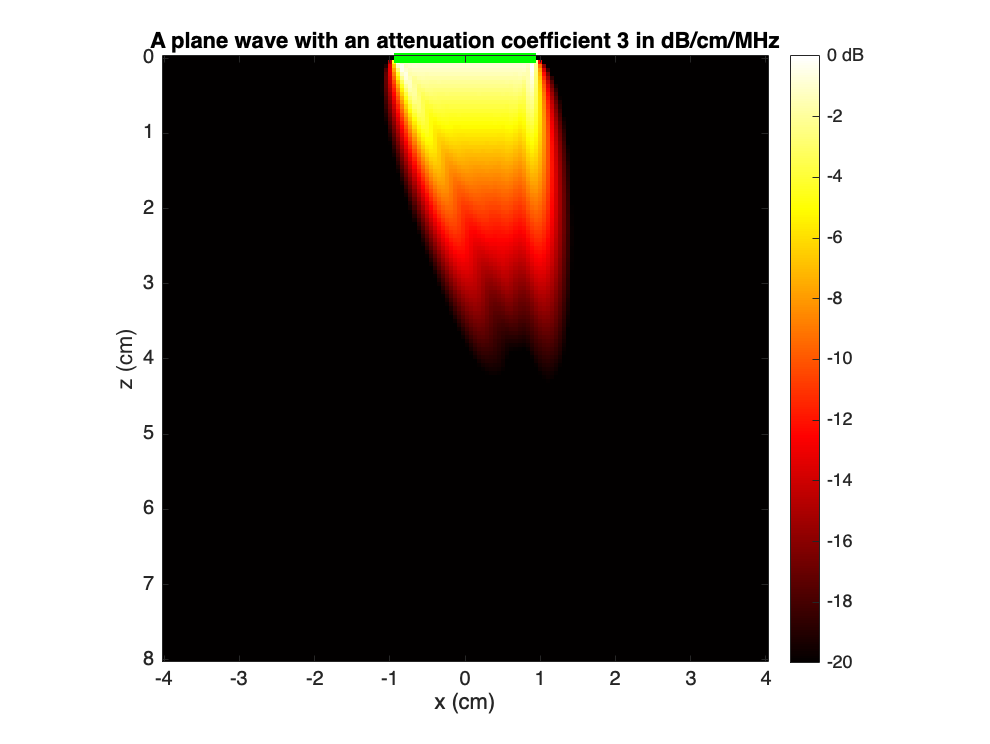

param = struct with fields:
             fc: 2700000
           kerf: 5.0000e-05
          width: 2.5000e-04
          pitch: 3.0000e-04
      Nelements: 64
      bandwidth: 74
         radius: Inf
         height: 0.0140
          focus: 0.0600
    attenuation: 3


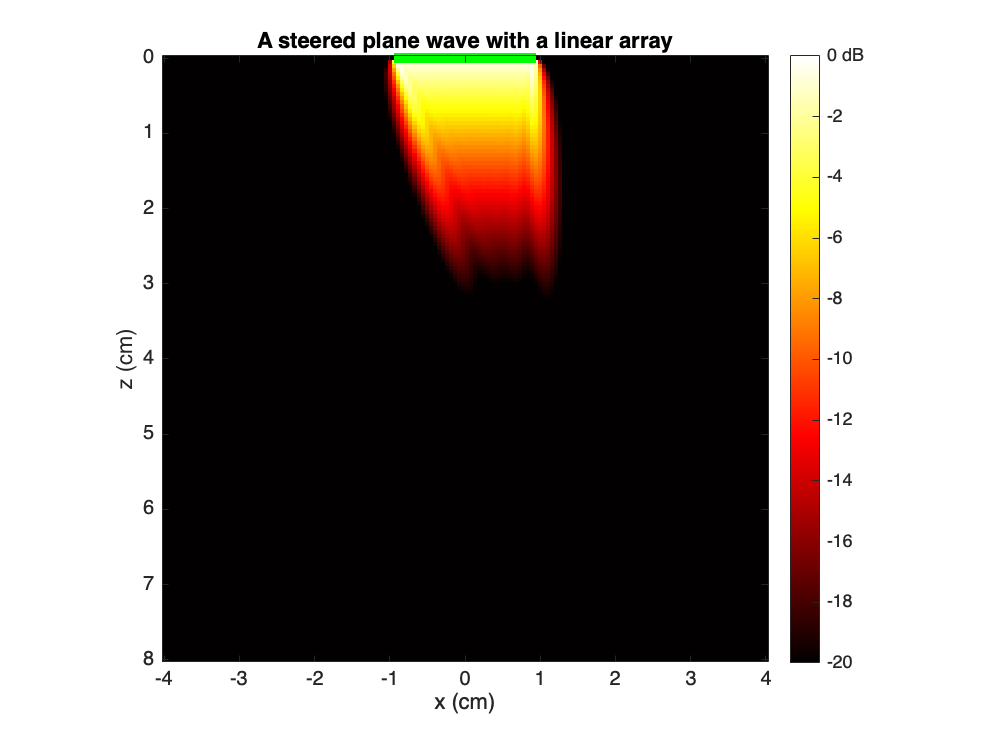

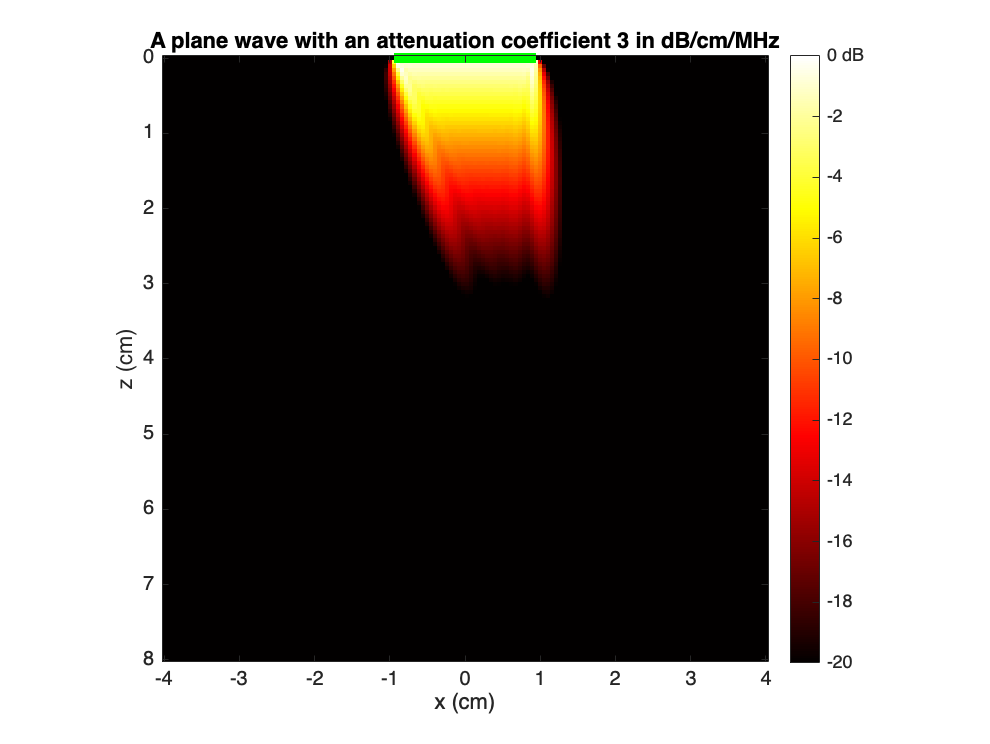

param = struct with fields:
             fc: 7000000
           kerf: 5.0000e-05
          width: 2.5000e-04
          pitch: 3.0000e-04
      Nelements: 64
      bandwidth: 74
         radius: Inf
         height: 0.0140
          focus: 0.0600
    attenuation: 3


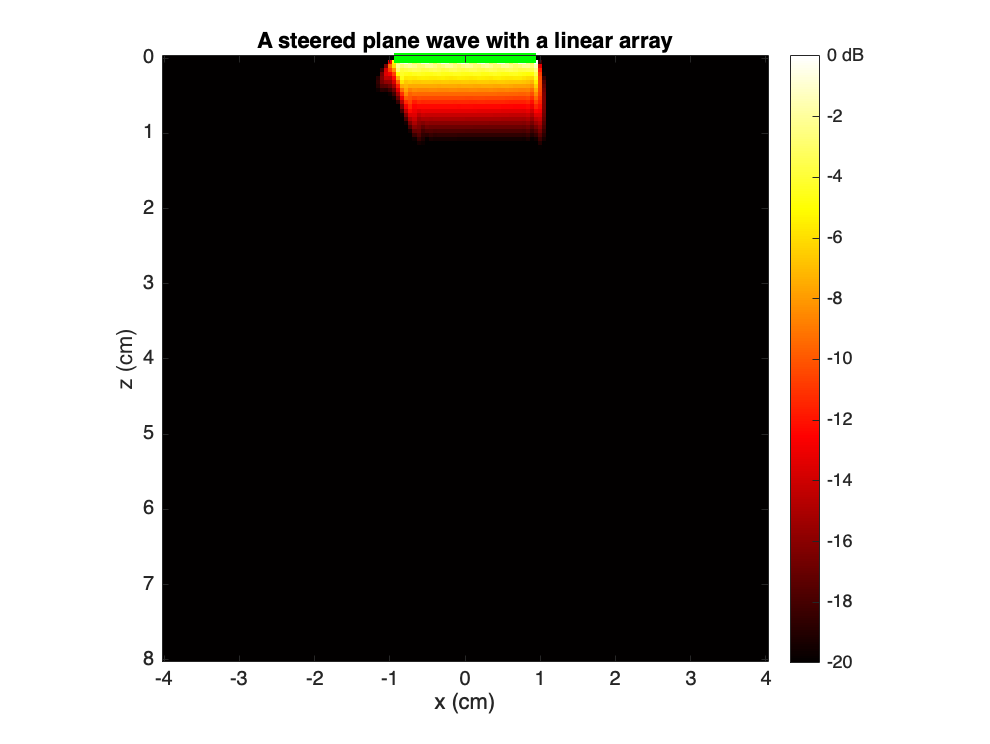

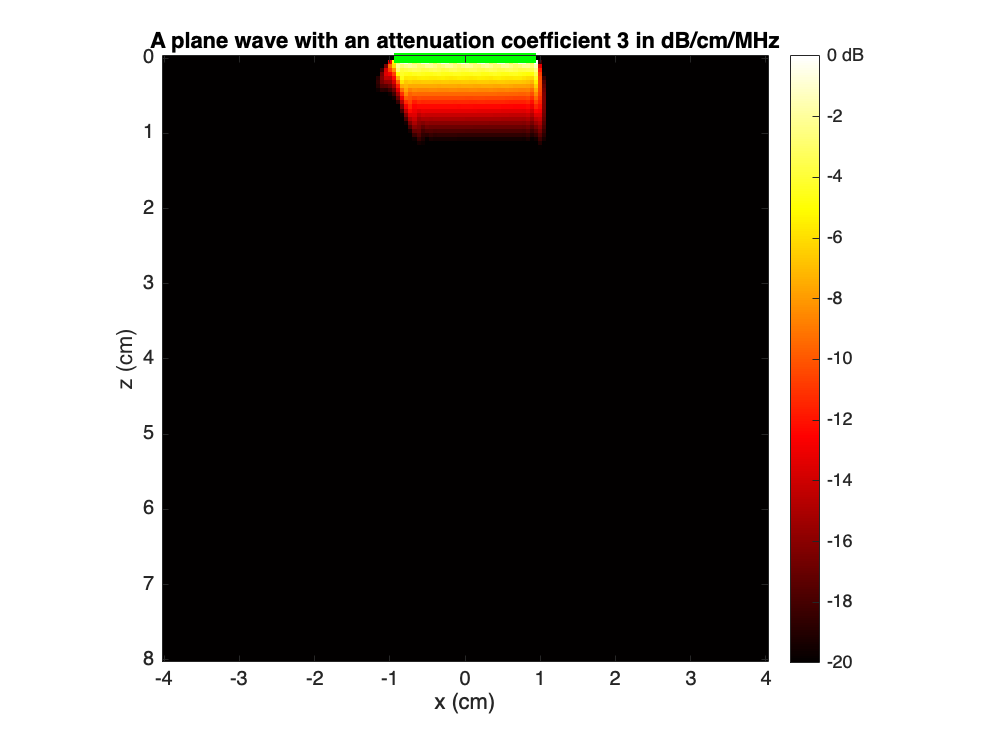

param = getparam('P4-2v');

freq_linear = [2e6, 2.7e6, 7e6]; %frequency in MhZ 

for i = 1:length(freq_linear )

    param = setfield(param,'fc',freq_linear (i))


    tilt = 10/180*pi; % tilt angle in rad
    txdel = txdelay(param,tilt); % in s
    
    
    x = linspace(-4e-2,4e-2,150); % in m
    z = linspace(0,8e-2,150); % in m
    [x,z] = meshgrid(x,z);
    
    
    P = pfield(x,z,txdel,param);
    
    
    figure
    imagesc(x(1,:)*1e2,z(:,1)*1e2,20*log10(P/max(P,[],'all')))
    caxis([-20 0]) % dynamic range = [-20,0] dB
    c = colorbar;
    c.YTickLabel{end} = '0 dB';
    colormap hot
    axis equal ij tight
    xlabel('x (cm)'), ylabel('z (cm)')
    title('A steered plane wave with a linear array')
    
    % Calculate the positions of the element centers.
    L = param.pitch*(param.Nelements-1); % array aperture (in m)
    xe = linspace(-0.5,0.5,param.Nelements)*L;
    ze = zeros(1,param.Nelements);
    hold on
    plot(xe*1e2,ze*1e2,'g','Linewidth',5)
    hold off
    %
%     arr = [0.1, 0.3, 0.5, 1.5, 2.5, 3];  % attenuation coefficient (in dB/cm/MHz)
%     for j = 1:length(arr)


%     param.attenuation = arr(j);  
    param.attenuation = 3;  
    P = pfield(x,z,txdel,param);
    
    figure
    imagesc(x(1,:)*1e2,z(:,1)*1e2,20*log10(P/max(P,[],'all')))
    caxis([-20 0]) % dynamic range = [-20,0] dB
    c = colorbar;
    c.YTickLabel{end} = '0 dB';
    colormap hot
    axis equal ij tight
    xlabel('x (cm)'), ylabel('z (cm)')
    title('A plane wave with an attenuation coefficient 3 in dB/cm/MHz')
    
    hold on
    plot(xe*1e2,ze*1e2,'g','Linewidth',5)
    hold off
%     end
end